Problem 13

clear
syms t m real positive
g = 9.81;
v0 = 20*[cosd(60); sind(60)]

v0 =    10.0000
   17.3205


a = [0; -g]

a =          0
   -9.8100


v = v0 + a*t

$$v = \left(\begin{array}{c} 10\\ 10\,\sqrt{3}-\frac{981\,t}{100} \end{array}\right)$$

Find top position at which vertical component of velocity is zero

ttop = solve(v(2)==0,t), vpa(ttop)

$$ttop = \frac{1000\,\sqrt{3}}{981}$$

$$ans = 1.7655971534850940810677332737063$$

vtop = subs(v,t,ttop)

$$vtop = \left(\begin{array}{c} 10\\ 0 \end{array}\right)$$

r = v0*t + 1/2*a*t^2

$$r = \left(\begin{array}{c} 10\,t\\ 10\,\sqrt{3}\,t-\frac{981\,t^{2}}{200} \end{array}\right)$$

rtop = subs(r,t,ttop)

$$rtop = \left(\begin{array}{c} \frac{10000\,\sqrt{3}}{981}\\ \frac{5000}{327} \end{array}\right)$$

double(rtop)

ans =    17.6560
   15.2905


Explosion occurs and linear momentum conserves

syms vbul real
eq = vtop(1)*m == vbul*m/2

$$eq = 10\,m=\frac{m\,\mathrm{vbul}}{2}$$

vbul = solve(eq,vbul)

$$vbul = 20$$

Bullet start to fly after explostion with initial speed of vbul = 20 m/s at rtop and t = 0

v0 = [vbul; 0]

$$v0 = \left(\begin{array}{c} 20\\ 0 \end{array}\right)$$

r = rtop + v0*t + 1/2*a*t^2

$$r = \left(\begin{array}{c} 20\,t+\frac{10000\,\sqrt{3}}{981}\\ \frac{5000}{327}-\frac{981\,t^{2}}{200} \end{array}\right)$$

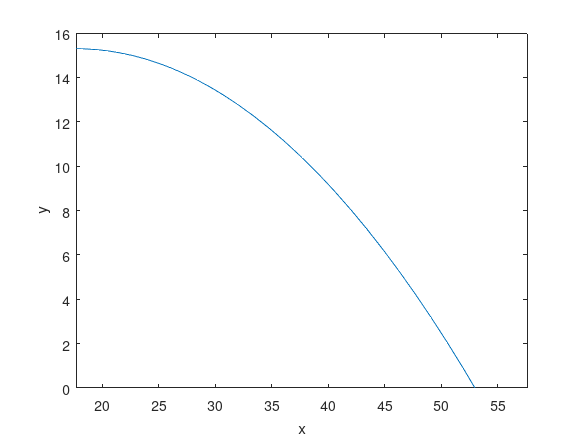

fplot(r(1),r(2),[0 2]), ylim([0 16]), xlabel('x'), ylabel('y')

tg = solve(r(2)==0,t)   % the t the bullet reaches the ground

$$tg = \frac{1000\,\sqrt{3}}{981}$$

xdist = double(subs(r(1),t,tg))

xdist = 52.9679

How far from the gun does the bullet land? 

dist = double(rtop(1) + xdist)

dist = 70.6239